# 对比Pelicun和PACT结果

## 依赖项

需要在windows命令行窗口中安装Pelicun

pip install pelicun

## 参数

i_IM = 6; % 绘图烈度

## PACT

PACT的计算结果文件：参考ExampleOfficeBuilding5.xml文件夹

## Pelicun

### 获取 Demand

从PACT中导出复制到demands.csv文件中

demandfile = 'demands.csv';
PACT_DemandFile = 'PACT_DemandFile.csv';
% 读取PACT EDP
T = readtable(PACT_DemandFile,'VariableNamingRule','preserve','NumHeaderLines',11);
rowPID = (T{:,'Intensity #'}==i_IM) & (T{:,'Demand Type'}=="Story Drift Ratio");
rowPFA = (T{:,'Intensity #'}==i_IM) & (T{:,'Demand Type'}=="Acceleration");
rowRID = (T{:,'Intensity #'}==i_IM) & (T{:,'Demand Type'}=="Residual Drift");
col = contains(T.Properties.VariableNames,'EQ');
% 读取 Sa
T_Sa = readtable(PACT_DemandFile,'VariableNamingRule','preserve',Range='2:10');
Sa = T_Sa{i_IM,'SA(T)'};
Sa = Sa.*9.8;
% 写入demands.csv
T_EDP = readtable(demandfile,'VariableNamingRule','preserve','ReadRowNames',true);
T_EDP{:,contains(T_EDP.Properties.VariableNames,'PFA')} = T{rowPFA,col}'.*9.8;
T_EDP{:,contains(T_EDP.Properties.VariableNames,'PID')} = T{rowPID,col}';
colind = contains(T_EDP.Properties.VariableNames,'RID');
T_EDP{:,colind} = repmat(T{rowRID,col}',1,size(colind,1));
T_EDP{:,contains(T_EDP.Properties.VariableNames,'SA')} = Sa;
writetable(T_EDP,demandfile,'WriteRowNames',true);

### 运行 DL_calculation.py

创建command命令

configFile = 'input.json';
command = ['python DL_calculation.py ', ...
    '-c ', configFile];

创建批处理文件

BatFile = 'PelicunCal.bat';
fileID = fopen(BatFile,'w');
fprintf(fileID, 'call %s %s\n', ... 
    "F:\anaconda3\Scripts\activate.bat", "F:\anaconda3\"); %conda环境
currentFolder = pwd;
fprintf(fileID, 'cd /d %s\n', string(currentFolder));
fprintf(fileID, '%s',command);
fclose(fileID);

利用批处理文件激活conda环境，运行pelicun

system(BatFile);

 
H:\CMP_PACTvsPelicun>call F:\anaconda3\Scripts\activate.bat F:\anaconda3\  
2024-04-27T01:27:44Z First line of DL_calculation 
2024-04-27T01:27:44Z Initializing pelicun calculation... 
WARNING in H:/CMP_PACTvsPelicun/DL_calculation.py at line 150 
Setting an item of incompatible dtype is deprecated and will raise in a future error of pandas. Value 'mps2' has dtype incompatible with float64, please explicitly cast to a compatible dtype first. 
 
WARNING in H:/CMP_PACTvsPelicun/DL_calculation.py at line 171 
Setting an item of incompatible dtype is deprecated and will raise in a future error of pandas. Value 'rad' has dtype incompatible with float64, please explicitly cast to a compatible dtype first. 
 
WARNING in H:/CMP_PACTvsPelicun/DL_calculation.py at line 356 
Setting an item of incompatible dtype is deprecated and will raise in a future error of pandas. Value 'ea' has dtype incompatible with float64, please explicitly cast to a compatible dtype first. 
 
WARNING in site-packages

### 读取结果

维修费用CDF

A = readmatrix('DL_summary.csv');
x_RC_Pel = A(:,2);
% figure
% ecdf(A(:,2));

顺序维修时间CDF

- 45.47个工人每层，需要自己考虑工人数量

figure
x_RT_Pel = A(:,4); % 3 平行； 4 顺序
ind_rep = A(:,5)==0 & A(:,6)==0; % 可修复的情形的索引
WorkersPerStory = 45.47;
x_RT_Pel(ind_rep) = x_RT_Pel(ind_rep)./WorkersPerStory;
% ecdf(A(:,4));

倒塌概率和不可修复概率

fprintf('倒塌概率：%f ;\n不可修复概率：%f ;\n', sum(A(:,5))/size(A,1), sum(A(:,6))/size(A,1));

倒塌概率：0.084000 ;
不可修复概率：0.060000 ;


## 对比

### 对比绘图

PACT_diroutput = 'ExampleOfficeBuilding5.xml';

维修费用

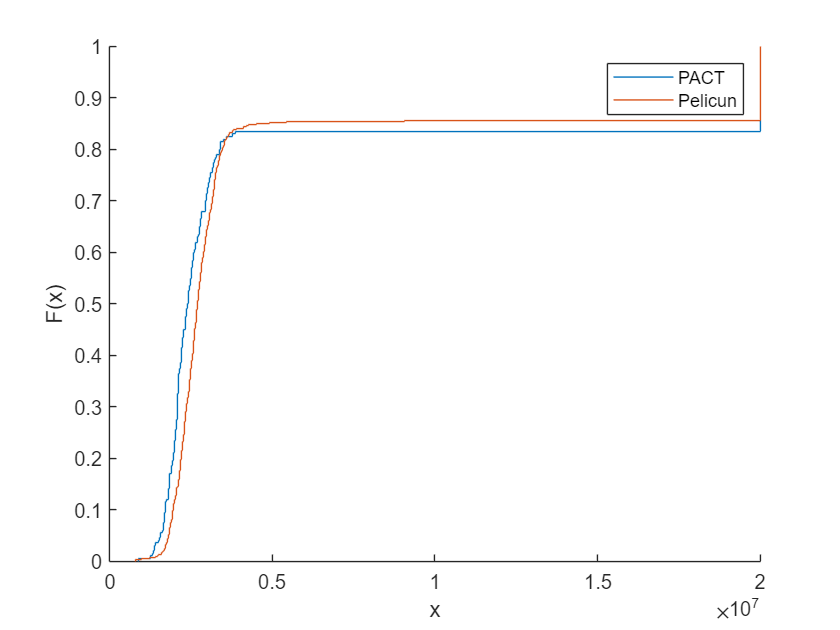

A = readmatrix(fullfile(PACT_diroutput,'RealCost_AllFloorsAllDirsAllPGs.csv'));
figure
hold on
ecdf(A(i_IM,2:end));
ecdf(x_RC_Pel);
ax = gca;
ax.XLim(1) = 0;
legend('PACT','Pelicun');

维修时间

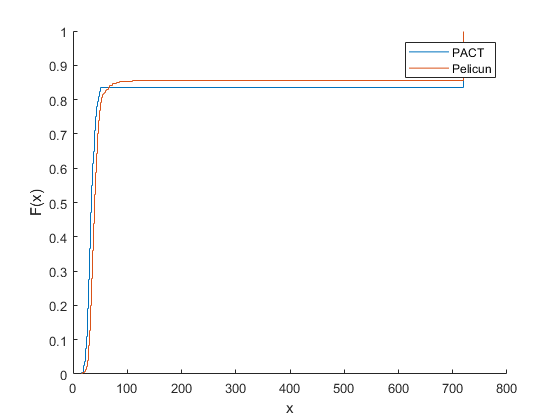

A = readmatrix(fullfile(PACT_diroutput,'RealTime_AllFloorsAllDirsAllPGs.csv'));
figure
hold on
ecdf(A(i_IM,2:end));
ecdf(x_RT_Pel);
ax = gca;
ax.XLim(1) = 0;
legend('PACT','Pelicun');

倒塌概率和不可修复概率

A = readmatrix(fullfile(PACT_diroutput,'RealCollapses_All.csv'),'OutputType','string');
fprintf('倒塌概率：%f ;\n', 1 - sum(A(i_IM,2:end)=="None")/(size(A,2)-1));

倒塌概率：0.085000 ;


A = readmatrix(fullfile(PACT_diroutput,'RealResidualDrifts_All.csv'),'OutputType','string');
fprintf('不可修复概率：%f ;\n', sum(A(i_IM,2:end)=="True")/(size(A,2)-1));

不可修复概率：0.080000 ;
